clc
clear

data = readmatrix("Data/CurrentConsumption.csv");
PWM = data(:,1);
current = [0 ;data(:,2)].';
omega = 1059*([1; PWM].'-ones(1,11));
p = current .* (linspace(0,1,11)*14.2);


Scatter plot of the data

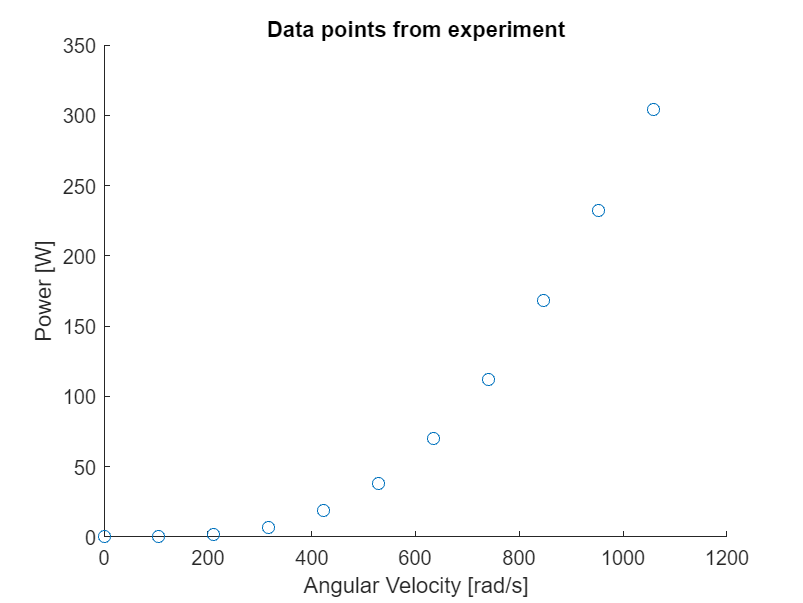

figure()
scatter(omega,p,'Color','red')
title('Data points from experiment')
xlabel("Angular Velocity [rad/s]")
ylabel("Power [W]")
saveas(gcf,'Images/Power_Draw_meas','epsc')

Regression

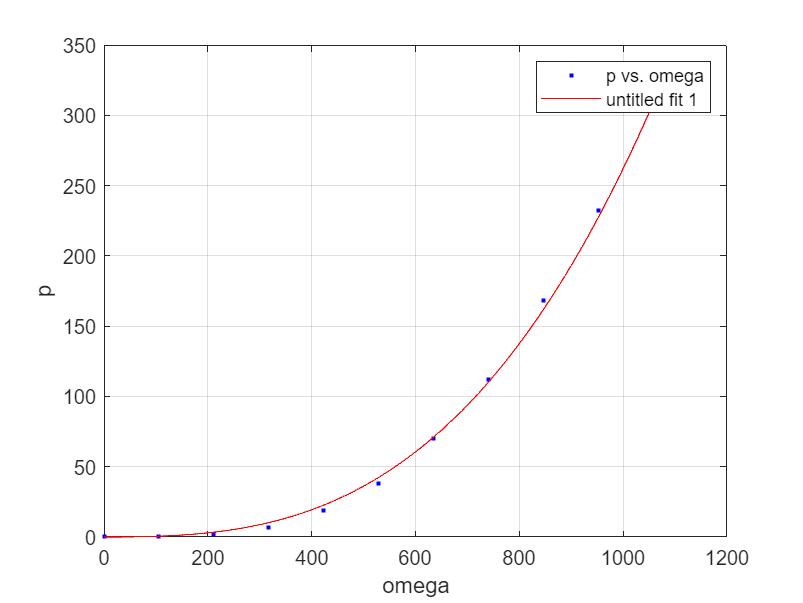

fitresult =      Linear model Poly3:
     fitresult(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients (with 95% confidence bounds):
       p1 =   2.354e-07  (2.031e-07, 2.676e-07)
       p2 =   2.678e-05  (-3.418e-06, 5.698e-05)
       p3 =   5.551e-23  (fixed at bound)
       p4 =           0  (fixed at bound)

gof = struct with fields:
           sse: 138.2021
       rsquare: 0.9988
           dfe: 9
    adjrsquare: 0.9986
          rmse: 3.9186


[fitresult, gof] = createFit2(omega,p)

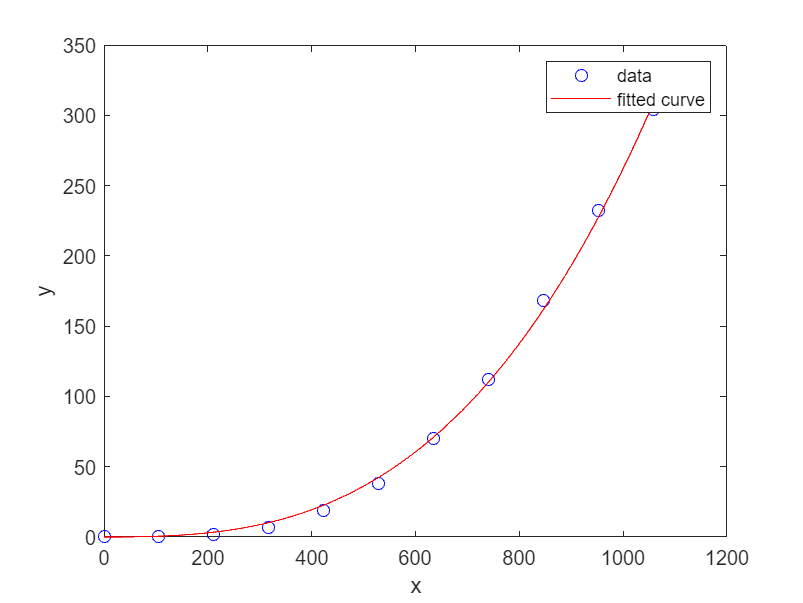

plot( fitresult,'r-', omega, p,'bo' );


y2 = fitresult.p1 * omega.^3 + fitresult.p1 * omega.^2;
y = @(x) 2.35e-07 * x.^3 + 2.68e-5 * x.^2;

SSR = sum((y(omega).' - p.').^2);
% Total sum of squares
TSS = sum(((p.' - mean(p)).^2));
% R squared
Rsquared = 1 - SSR/TSS

Rsquared = 0.9988

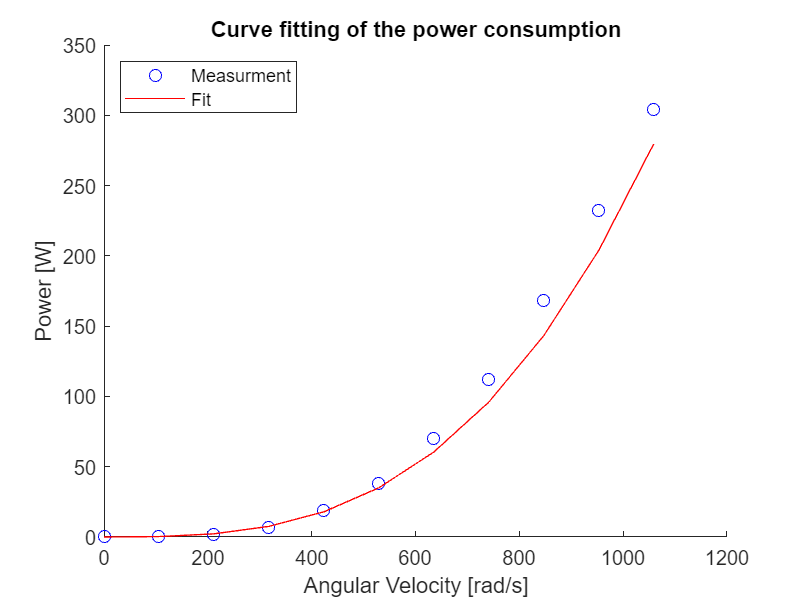




figure()
hold on
plot(omega,p,'bo')
plot(omega,y2,'Color','red')
title('Curve fitting of the power consumption')
legend({'Measurment','Fit'},"Location","northwest")
xlabel("Angular Velocity [rad/s]")
ylabel("Power [W]")
saveas(gcf,'Images/Power_Draw','epsc')
hold off